# Varying Parameters analysis

**Author(s): Vanja Vlasov, Systems Biochemistry Group, LCSB, University of Luxembourg.**

**Reviewer(s): Thomas Pfau, Systems Biology Group, LSRU, University of Luxembourg.**

**Ines Thiele, Molecular Systems Physiology Group, LCSB, University of Luxembourg**

**Almut Heinken, Molecular Systems Physiology Group, LCSB, University of Luxembourg**

In this tutorial, we show how computations are performed by varying one or two parameters over a fixed range of numerical values.

## EQUIPMENT SETUP

If necessary, initialise the cobra toolbox:

initCobraToolbox;



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules ... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.
 > TranslateSBML is installed and working properly.
 > Configuring sol

For solving linear programming problems in the analysis, certain solvers are required:

changeCobraSolver ('gurobi', 'all', 1);

 > Solver for LPproblems has been set to glpk.
 > Solver for MILPproblems has been set to glpk.
 > Solver glpk not supported for problems of type MIQP. Currently used: tomlab_cplex 
 > Solver glpk not supported for problems of type NLP. Currently used: matlab 
 > Solver glpk not supported for problems of type QP. Currently used: qpng 


%changeCobraSolver ('glpk', 'all', 1);

The present tutorial can run with `'glpk``'` package, which does not require additional installation and configuration. Although, for the analysis of large models is recommended to use the `'gurobi'` package. For detail information, refer to the solver installation guide: [https://github.com/opencobra/cobratoolbox/blob/master/docs/source/installation/solvers.md](https://github.com/opencobra/cobratoolbox/blob/master/docs/source/installation/solvers.md)

## PROCEDURE

Before proceeding with the simulations, the path for the model needs to be set up. In this tutorial, the used model is the generic model of human metabolism, Recon 3 [1]. Therefore, we assume, that the cellular objectives include energy production or optimisation of uptake rates and by-product secretion for various physiological functions of the human body. If Recon 3 is not available, please use Recon 2.

%For Recon3D Change the model
modelFileName = 'Recon2.0model.mat';
modelDirectory = getDistributedModelFolder(modelFileName); %Look up the folder for the distributed Models.
modelFileName= [modelDirectory filesep modelFileName]; % Get the full path. Necessary to be sure, that the right model is loaded
model = readCbModel(modelFileName);


If Recon2 is used, the reaction nomenclature needs to be adjusted.

model.rxns(find(ismember(model.rxns,'EX_glc(e)')))={'EX_glc_D[e]'};
model.rxns(find(ismember(model.rxns,'EX_o2(e)')))={'EX_o2[e]'};

## TROUBLESHOOTING

If there are multiple energy sources available in the model; Specifying more constraints is necessary. If we do not do that, we will have additional carbon and oxygen energy sources available in the cell and the maximal ATP production. 

To avoid this issue, all external carbon sources need to be closed.

%Closing the uptake of all energy and oxygen sources
for i=1:length(model.rxns)
    if strncmp(model.rxns{i},'EX_',3)
        model.subSystems{i}='Exchange/demand reaction';
    end
end
idx=strmatch('Exchange/demand reaction', model.subSystems);
c=0;
for i=1:length(idx)
    if model.lb(idx(i))~=0
        c=c+1;
        uptakes{c}=model.rxns{idx(i)};
    end
end

modelalter = model;
modelalter = changeRxnBounds(modelalter, uptakes, 0, 'l');

% The alternative way to do that, in case you were using another large model, 
% that does not contain defined Subsystem is
% to find uptake exchange reactions with following codes:
% [selExc, selUpt] = findExcRxns(model);
% uptakes = model.rxns(selUpt);
% Selecting from the exchange uptake reactions those 
% which contain at least 1 carbon in the metabolites included in the reaction:
% subuptakeModel = extractSubNetwork(model, uptakes);
% hiCarbonRxns = findCarbonRxns(subuptakeModel,1);
% Closing the uptake of all the carbon sources
% modelalter = model;
% modelalter = changeRxnBounds(modelalter, hiCarbonRxns, 0, 'l');

## Robustness analysis

Robustness analysis is applied to estimate and visualise how changes in the concentration of an environmental parameter (exchange rate) or internal reaction effect on the objective [2]. If we are interested in varying $$v_{j}$ between two values, i.e., $$v_{j,min}$ and $$v_{j,max}$, we can solve $$l$ optimisation problems:


$$\begin{array}{ll}
\max Z_{k}= c^{T}v \\
\text{s.t.} & k =1,...,l,\\
& Sv=0,\\
\text{fixing} & v_{j}=v_{j,min}+ \frac{(k-1)}{(l-1)}*(v_{j,max}-v_{j,min})\\
\text{constraints} & v_{i,min}\leq v_{i} \leq v_{i,max}, i=1,...,n,i \neq j
 \end{array}$$


The function `robustnessAnalysis()` is used for this analysis:

% [controlFlux, objFlux] = robustnessAnalysis(model, controlRxn, nPoints,...
%      plotResFlag, objRxn,objType)

where inputs are a COBRA model, a reaction that has been analysed and optional inputs:

% INPUTS
% model         COBRA model structure
% controlRxn    Reaction of interest whose value is to be controlled
%
% OPTIONAL INPUTS
% nPoints       Number of points to show on plot (Default = 20)
% plotResFlag   Plot results (Default true)
% objRxn        Objective reaction to be maximized
%               (Default = whatever is defined in model)
% objType       Maximize ('max') or minimize ('min') objective
%               (Default = 'max')
%
% OUTPUTS
% controlFlux   Flux values within the range of the maximum and minimum for
%               a reaction of interest
% objFlux       Optimal values of objective reaction at each control
%               reaction flux value

Here, we will investigate how robust the maximal ATP production of the network (i.e., the maximal flux through '`DM_atp_c_'`) is with respect to varying glucose uptake rates and fixed oxygen uptake. 

modelrobust = modelalter;
modelrobust = changeRxnBounds(modelrobust, 'EX_o2[e]', -17, 'b');
AtpRates = zeros(21, 1);
for i = 0:20
    modelrobust = changeRxnBounds(modelrobust, 'EX_glc_D[e]', -i, 'b');
    modelrobust = changeObjective(modelrobust, 'DM_atp_c_');
    FBArobust = optimizeCbModel(modelrobust, 'max');
    AtpRates(i+1) = FBArobust.f;
end
plot (1:21, AtpRates)

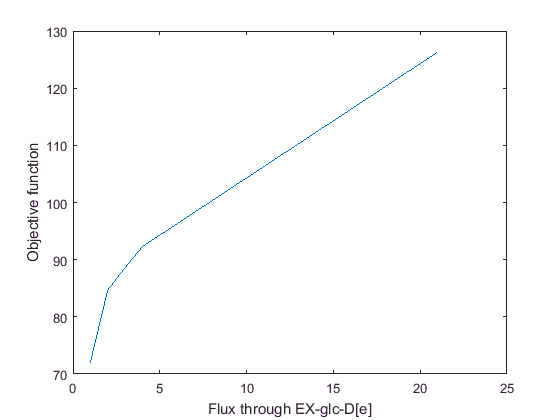

xlabel('Flux through EX-glc-D[e]')
ylabel('Objective function')

We can also investigate the robustness of the maximal ATP production when the available glucose amount is fixed, while different levels of oxygen are available.

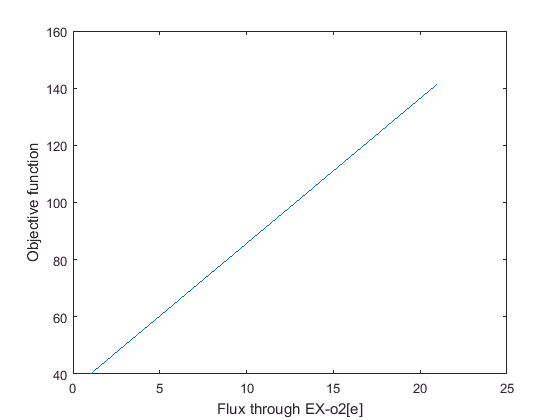

modelrobustoxy = modelalter;
modelrobustoxy = changeRxnBounds(modelrobustoxy, 'EX_glc_D[e]', -20, 'b');
AtpRatesoxy = zeros(21, 1);
for i = 0:20
    modelrobustoxy = changeRxnBounds(modelrobustoxy, 'EX_o2[e]', -i, 'b');
    modelrobustoxy = changeObjective(modelrobustoxy, 'DM_atp_c_');
    FBArobustoxy = optimizeCbModel(modelrobustoxy, 'max');
    AtpRatesoxy(i+1) = FBArobustoxy.f;
end
plot (1:21, AtpRatesoxy)
xlabel('Flux through EX-o2[e]')
ylabel('Objective function')

-        **Double robust analysis**

Performs robustness analysis for a pair of reactions of interest and an objective of interest. The double robust analysis is implemented with the function `doubleRobustnessAnalysis()`.

% [controlFlux1, controlFlux2, objFlux] = doubleRobustnessAnalysis(model,...
%  controlRxn1, controlRxn2, nPoints, plotResFlag, objRxn, objType)

The inputs are a COBRA model, two reactions for the analysis and optional inputs:

%INPUTS
% model         COBRA model to analyse,
% controlRxn1   The first reaction for the analysis,
% controlRxn2   The second reaction for the analysis;
%
%OPTIONAL INPUTS
% nPoints       The number of flux values per dimension (Default = 20)
% plotResFlag   Indicates whether the result should be plotted (Default = true)
% objRxn        is objective to be used in the analysis (Default = whatever
%               is defined in model)
% objType       Direction of the objective (min or max)
%               (Default = 'max')

Double robustness analysis in progress ...
1%      [                                        ]2%      [                                        ]3%      [.                                       ]4%      [.                                       ]5%      [..                                      ]6%      [..                                      ]7%      [..                                      ]8%      [...                                     ]9%      [...                                     ]10%     [....                                    ]11%     [....                                    ]12%     [....                                    ]13%     [.....                                   ]14%     [.....                                   ]15%     [......                                  ]16%     [......                                  ]17%     [......                                  ]18%     [.......                                 ]19%     [.......                                 ]20%    

controlFlux1 =   -20.0000
  -17.7225
  -15.4451
  -13.1676
  -10.8902
   -8.6127
   -6.3353
   -4.0578
   -1.7804
    0.4971


controlFlux2 =   -17.0000
  -15.1111
  -13.2222
  -11.3333
   -9.4444
   -7.5556
   -5.6667
   -3.7778
   -1.8889
    0.0000


objFlux =   126.2944  116.7061  107.1179   97.5296   87.9413   78.3531   68.7648   59.1765   49.5883   40.0000
  121.7395  112.1512  102.5630   92.9747   83.3864   73.7982   64.2099   54.6216   45.0334   35.4451
  117.1846  107.5963   98.0081   88.4198   78.8315   69.2433   59.6550   50.0667   40.4785   30.8902
  112.6297  103.0414   93.4532   83.8649   74.2766   64.6884   55.1001   45.5118   35.9236   26.3353
  108.0748   98.4865   88.8983   79.3100   69.7217   60.1335   50.5452   40.9569   31.3686   21.7804
  103.5199   93.9316   84.3434   74.7551   65.1668   55.5785   45.9903   36.4020   26.8137   17.2255
   98.9650   89.3767   79.7884   70.2002   60.6119   51.0236   41.4354   31.8471   22.2588   12.6706
   94.4101   84.8218   75.2335   65.6453   56.0570   46.4687   36.8805   27.2922   17.7039    8.1157
   87.7466   78.7732   69.7997   60.8263   51.5021   41.9138   32.3256   22.7373   13.1490    3.5608
   33.5029         0         0         0         0         0         0         0 

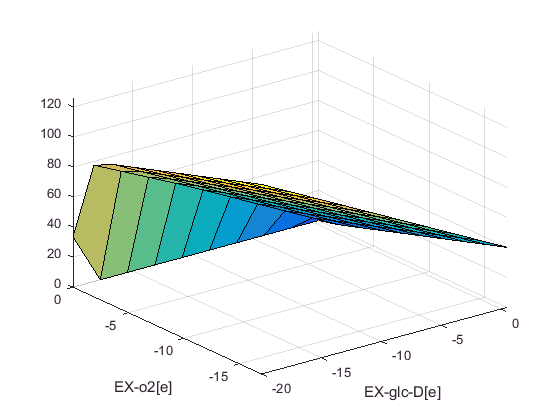

modeldrobustoxy = modelalter;
modeldrobustoxy = changeRxnBounds(modeldrobustoxy, 'EX_glc_D[e]', -20, 'l');
modeldrobustoxy = changeRxnBounds(modeldrobustoxy, 'EX_o2[e]', -17, 'l');
[controlFlux1, controlFlux2, objFlux] = doubleRobustnessAnalysis(modeldrobustoxy,...
    'EX_glc_D[e]', 'EX_o2[e]', 10, 1, 'DM_atp_c_', 'max')

## **Phenotypic phase plane analysis (PhPP)**

The PhPP is a method for describing in two or three dimensions, how the objective function would change if additional metabolites were given to the model [3]. 

Essentially PhPP performs a `doubleRobustnessAnalysis()`, with the difference that shadow prices are retained. The code is as follows-

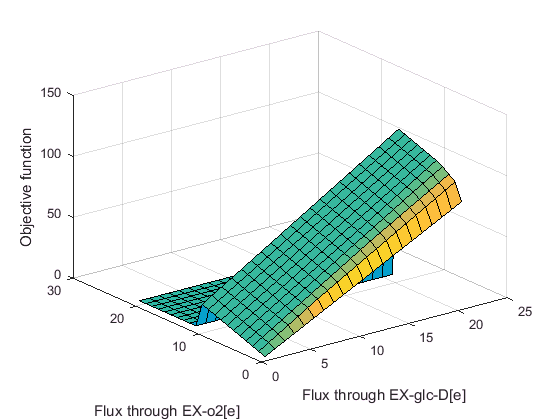

modelphpp = modelalter;
ATPphppRates = zeros(21);
for i = 0:10
    for j = 0:20
        modelphpp = changeRxnBounds(modelphpp, 'EX_glc_D[e]', -i, 'b');
        modelphpp = changeRxnBounds(modelphpp, 'EX_o2[e]', -j, 'b');
        modelphpp = changeObjective(modelphpp, 'DM_atp_c_');
        FBAphpp = optimizeCbModel(modelphpp, 'max');
        ATPphppRates(i+1,j+1) = FBAphpp.f;
    end
end

surfl(ATPphppRates) % 3d plot
xlabel('Flux through EX-glc-D[e]')
ylabel('Flux through EX-o2[e]')
zlabel('Objective function')

To generate a 2D plot: `pcolor(ATPphppRates)`

Alternatively, use the function `phenotypePhasePlane()`. This function also draws the line of optimality, as well as the shadow prices of the metabolites from the two control reactions. In this case, control reactions are '`EX_glc_D[e]`' and '`EX_o2[e]`'. The line of optimality signifies the state wherein, the objective function is optimal. In this case it is '`DM_atp_c_`'.

generating PhPP

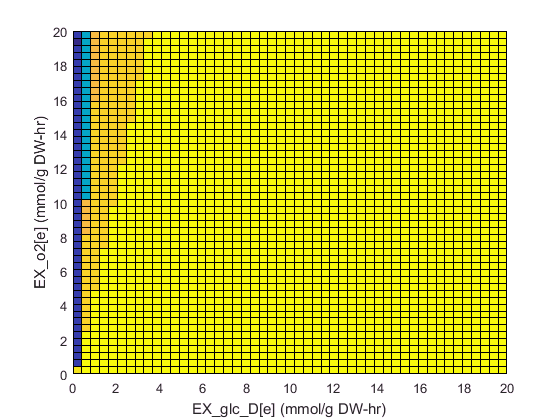

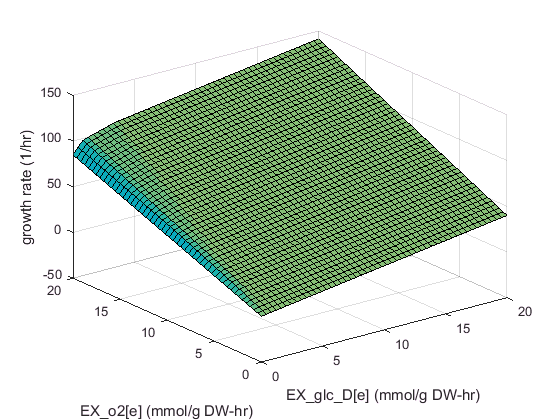

modelphpp = changeObjective (modelphpp, 'DM_atp_c_');
[growthRates, shadowPrices1, shadowPrices2] = phenotypePhasePlane(modelphpp,...
    'EX_glc_D[e]', 'EX_o2[e]');

## REFERENCES 

[1] Noronha A., et al. (2017). ReconMap: an interactive visualization of human metabolism. *Bioinformatics*., 33 (4): 605-607.

[2] Edwards, J.S. and and Palsson, B. Ø. (2000). Robustness analysis of the Escherichia coli metabolic network. *Biotechnology Progress, *16(6):927-39.

[3] Edwards, J.S., Ramakrishna, R. and and Palsson, B. Ø. (2002). Characterizing the metabolic phenotype: A phenotype phase plane analysis. *Biotechnology and Bioengineering*, 77:27-36.